# MATH.APP.450 Basic Course on Mathematical Modelling

The file "tls_points.txt" has a three-dimensional point cloud from a tree. The point cloud has been measured by lidar from [0 0 1.5]. The lidar is able to measure from the same direction only the object closest to it. The measured point can be a leaf, tree branch, tree trunk, or ground surface. There are no obstacles to the line connecting the measured point and the laser, the point [0 0 1.5], 

The purpose of the assignment is to compute, using a suitable model or more models, based on data, both the total area of leaves in the tree and an estimate for the number of leaves. The purpose is also to assess the reliability and accuracy of the methods used. Assumptions are allowed to make. Please tell what kind of  assumptions you are done. For example, one might assume that measurements was done in calm weather, in which case the positions of leaves and branches have not changed during measuremnets camping.  

The data used in the task is sourced from the Helios++ simulator website [https://uni-heidelberg.de/helios](https://uni-heidelberg.de/helios). In more detail, you can find out more with the help of the following article

Winiwarter, L., Esmorís Pena, A., Weiser, H., Anders, K., Martínez Sanchez, J., Searle, M., Höfle, B. (2022): **Virtual laser scanning with HELIOS++: A novel take on ray tracing-based simulation of topographic full-waveform 3D laser scanning**. *Remote Sensing of Environment*, 269, doi:10.1016/j.rse.2021.112772 ([www](https://www.sciencedirect.com/science/article/pii/S0034425721004922))

With the code below, you can load the data into Matlab into a matrix format (matrix Points), create a point cloud (variable Tree) and show it (pcshow). On the same figure there is a measuring device (lidar) with a red dot.

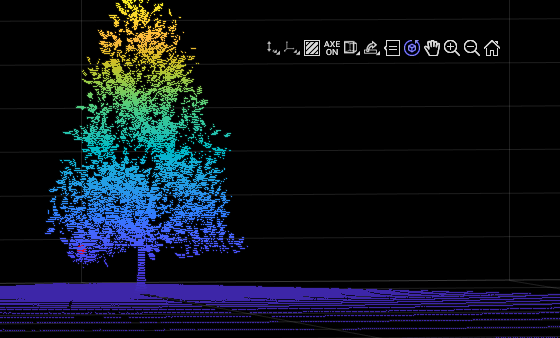

Points = table2array(readtable("tls_points.txt"));
Tree = pointCloud(Points);
pcshow(Tree)
hold on
lidar = [0 0 1.5];
plot3(lidar(1),lidar(2),lidar(3),'r.','MarkerSize',20)